График для Рис. 1: Зависимость величины мультипликатора от значений параметра.

clc; clear;
u_star = @(r) (1+2.*r.^2-sqrt(1+4.*r.^2))./(2.*r.^2);
mu = @(r) r.*((1-3.*u_star(r))/(2.*sqrt(u_star(r))));
r_interval = [0 1];
r_0 = sqrt(3)/2;
pr0 = plot(r_0,0,'Marker','.',"MarkerSize", 16);
text(r_0-0.01,-0.02,'$r_0$','Interpreter',"latex");
    ax = gca;
    ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; ax.Box = "off";
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.YLabel.Rotation = 0; ax.YLabel.Position = [0.05 0.45];
    ax.XLabel.String = '$r$'; ax.YLabel.String = '$\mu(r)$';
    hold on;
fplot(ax,mu,r_interval);

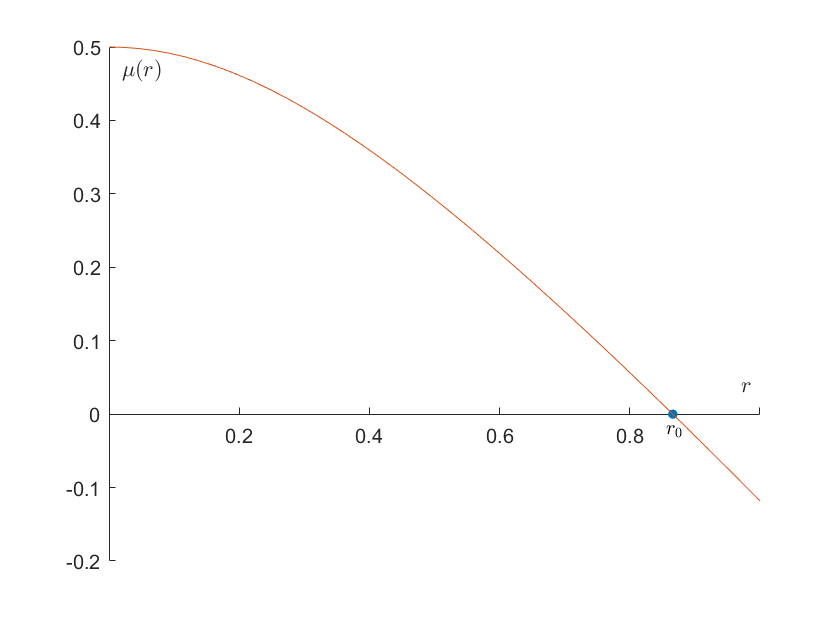

    hold off;

График для Рис. 2: устойчивая неподвижная точка

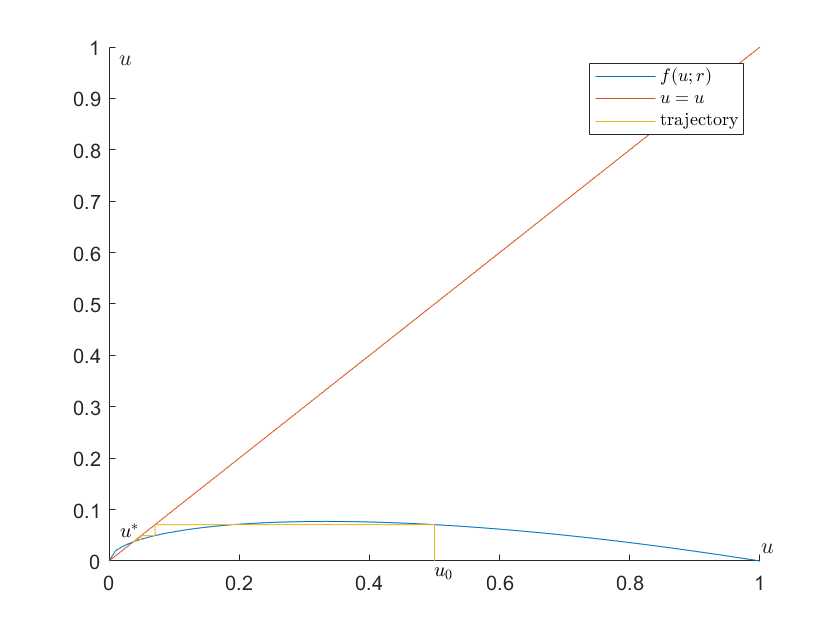

u0 = 0.5; r = 0.2;
plotTrajectory(u0, r);
hold on; 
text(u_star(r)-0.02,u_star(r)+0.02,'$u^*$','Interpreter',"latex");
hold off;

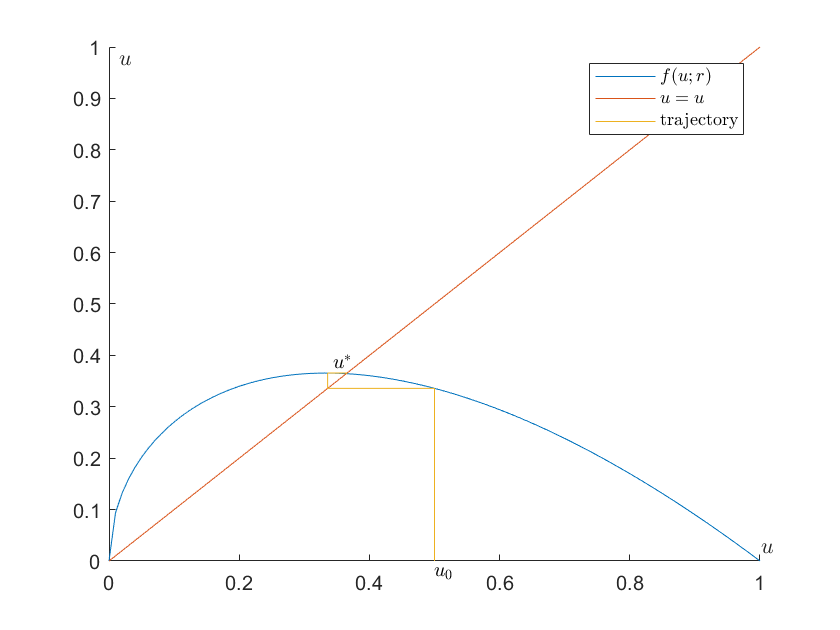

u0 = 0.5; r = 0.95;
plotTrajectory(u0, r);
hold on; 
text(u_star(r)-0.02,u_star(r)+0.02,'$u^*$','Interpreter',"latex");
hold off;

Нахождение циклов длины 2 и 3

ul = 0; ur = 1; rl = 0; rr = 3*sqrt(3)/2;
f  = @(u,r) r*sqrt(u)*(1-u);
f2 = @(u,r) f(f(u,r),r);
f3 = @(u,r) f(f(f(u,r),r),r);
    dfdu = @(u,r) r/(2*sqrt(u)) * (1-3*u);
    df2du = @(u,r) ((r^2)/(4*u)) * (1-3*u)^2;
    df3du = @(u,r) ((r^3)/(8*u*sqrt(u))) * (1-3*u)^3;
problem2 = @(x) problemk(x,f2,df2du);
problem3 = @(x) problemk(x,f3,df3du);
    options = optimset('TolFun',1e-12,'Display','off');
    solfun2 = @(x0) lsqnonlin(problem2,x0,[ul;rl],[ur;rr],options);
    solfun3 = @(x0) lsqnonlin(problem3,x0,[ul;rl],[ur;rr],options); 
sol2 = findAll(20,solfun2,2) %accuarate till 10^-3

sol2 =     0.2838    0.3980    0.4494    0.3980
    2.2685    2.0564    1.2176    2.0564


r0 = 2

r0 = 2

spec_problem2 = @(x) f2(x,r0) - x;
x1 = lsqnonlin(spec_problem2,0.4,ul,ur,options)

x1 = 0.4511

x2 = lsqnonlin(spec_problem2,0.7,ul,ur,options)

x2 = 0.7373

sol3 = findAll(20,solfun3,2.3)

sol3 =     0.0346
    0.1927


График для Рис.3: Устойчивый цикл длины 2 (r = 2, u0 = 0,5).

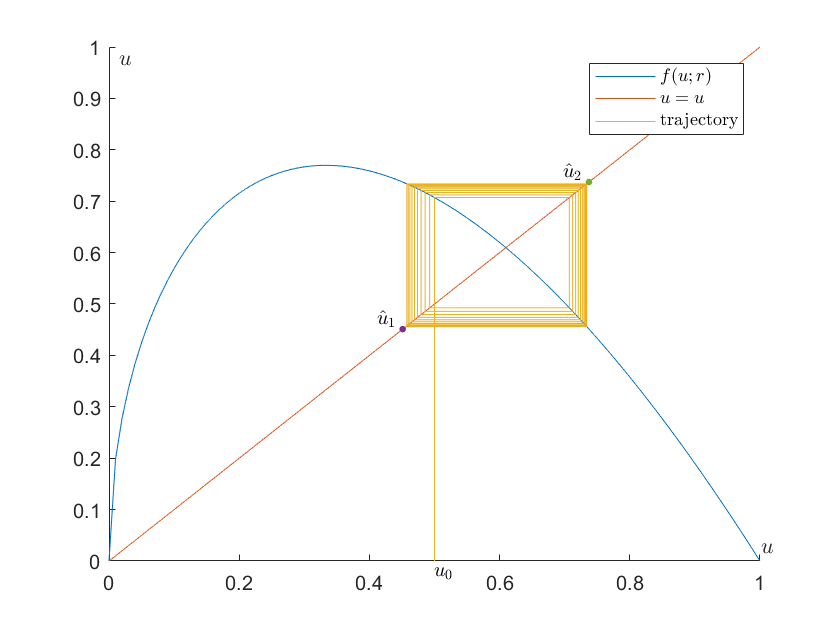

u0 = 0.5; r = 2;
plotTrajectory(u0,r);
hold on;
plot(x1,x1,'Marker','.',"MarkerSize",10); text(x1-0.04,x1+0.02,'$\hat u_1$','Interpreter',"latex");
plot(x2,x2,'Marker','.',"MarkerSize",10); text(x2-0.04,x2+0.02,'$\hat u_2$','Interpreter',"latex");
hold off;

График для Рис.3: Потеря устойчивости (r = 2,5,  u0 = 0,5).

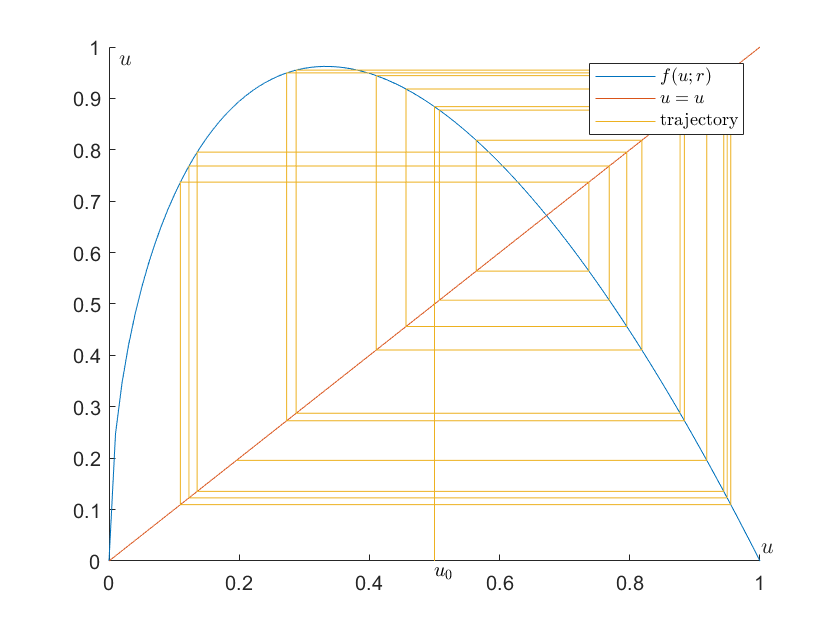

u0 = 0.5; r = 2.5;
plotTrajectory(u0,r);

График для Рис. 5: Бифуркационная диаграмма

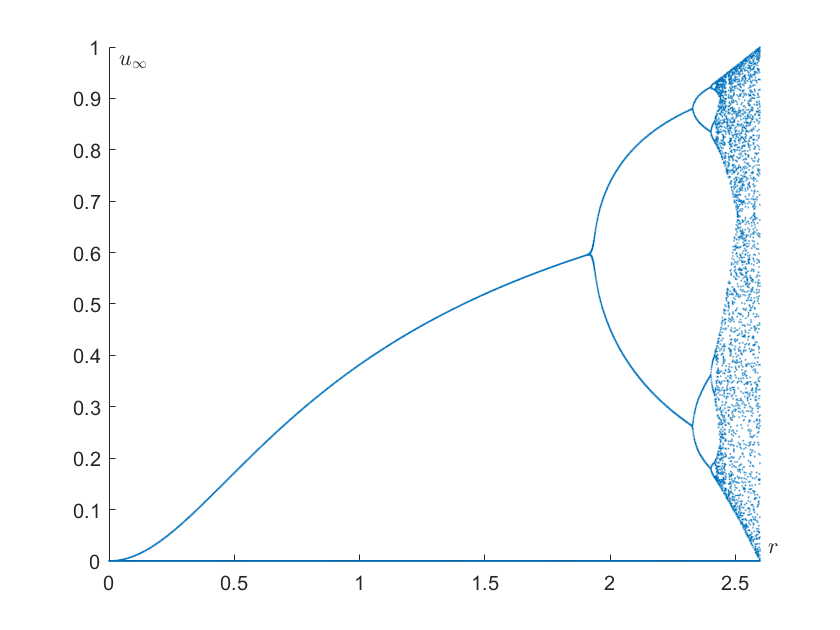

clear; clc;
f  = @(u,r) r*sqrt(u)*(1-u);
dr = 0.001; rlb = 0; rrb = 3*sqrt(3)/2;
u_density = 20; u0 = 0.5;
iters = 200;
Y = zeros(u_density); X = ones(u_density);

plot(0,0); hold on;
    ax = gca;
    ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; ax.Box = "off";
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.YLabel.Rotation = 0; ax.YLabel.Position = [0.1, 0.95];
    ax.XLim = [rlb rrb];
    ax.XLabel.Position = [rrb+0.05 0.05];
    ax.XLabel.String = '$r$'; ax.YLabel.String = '$u_{\infty}$';

for r = rlb:dr:rrb
    u = u0;
    X = ones(u_density)*r;
    for i = 1:iters
        u = f(u,r);
    end
    for i = 1:u_density
        u = f(u,r);
        Y(i) = u;
    end
    plot(X,Y,'.','MarkerSize',1,"Color",'#0072BD');
end
hold off;
exportgraphics(gcf,'pictures\fig5.png');

Показатель Ляпунова

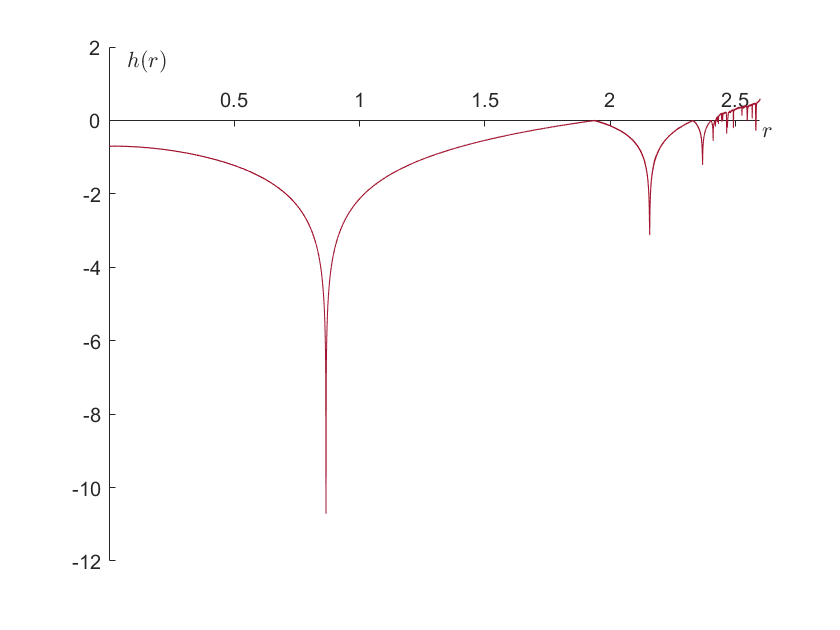

clear; clc;
f  = @(u,r) r*sqrt(u)*(1-u);
dfdu = @(u,r) r/(2*sqrt(u)) * (1-3*u);
dr = 0.001; rlb = 0; rrb = 3*sqrt(3)/2;
u_density = 20; u0 = 0.5;
inf = 1000;
R = rlb:dr:rrb;
H = zeros(1,size(R,2));

hold on;
for u1 = 0:0.05:1

j = 0;
for r = rlb:dr:rrb
    firstR = true;
    j = j + 1;
    u = u1; hn = 0;
    for i = 1:inf
        hn = hn + log(abs(dfdu(u,r)));
        u = f(u,r);
    end
    H(j) = hn;
end
H = H/inf;

plot(R,H,"Color",'#A2142F'); 
end
    ax = gca;
    ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; ax.Box = "off";
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.YLabel.Rotation = 0; ax.YLabel.Position = [0.15, 1.25];
    ax.XLim = [rlb rrb];
    ax.XLabel.Position = [rrb+0.05 0.05];
    ax.XLabel.String = '$r$'; ax.YLabel.String = '$h(r)$';
hold off;
exportgraphics(gcf,'pictures\lyap1.png');

Вспомогательные функции

function F = problemk(x,fk,dfkdu)
    F(1) = fk(x(1),x(2)) - x(1);
    F(2) = dfkdu(x(1),x(2)) - 0.1;
end

function sol = findAll(N,solfunk,r0)
    epsilon = 0.001;                %epsilon!
    u0 = 0; du0 = 1/N;
    sol = [];
    for i = 1:N
        u0 = u0 + du0;
        attempt = solfunk([u0;r0]);
        if isempty(sol) || (abs(sol(1,end) - attempt(1)) > epsilon)
            sol = [sol,attempt]; 
        end
    end
end

function plotTrajectory(u0,r)
    f  = @(u) r.*sqrt(u).*(1-u);
    X = 0:0.01:1; Y = f(X);
    pl1 = plot(X,Y);
        ax = gca;
        ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin'; ax.Box = "off";
        ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
        ax.XLabel.Position = [1.01 0.05];
        ax.YLabel.Rotation = 0; ax.YLabel.Position = [0.025 0.95]; ax.YLim = [0 1];
        ax.XLabel.String = '$u$'; ax.YLabel.String = '$u$';
    hold on;
    
    X = 0:0.1:1; Y = 0:0.1:1;
    pl2 = plot(X,Y);

    iters = 20; u0 = 0.5;
    X = zeros(2*iters+1,1); Y = zeros(2*iters+1,1); 
    u = u0;
    X(1) = u0; Y(1) = 0;
    for i = 1:(iters)
        X(2*i) = u; 
        u = f(u); Y(2*i) = u;
        X(2*i+1) = u; Y(2*i+1) = u;
    end
    pl3 = plot(X(1:end),Y(1:end));

    legend('$f(u;r)$','$u=u$','trajectory','Interpreter','latex','AutoUpdate','off');
    text(u0,-0.02,'$u_0$','Interpreter',"latex");
    hold off;
end

 
  